# Rescale an Image by Blocks

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

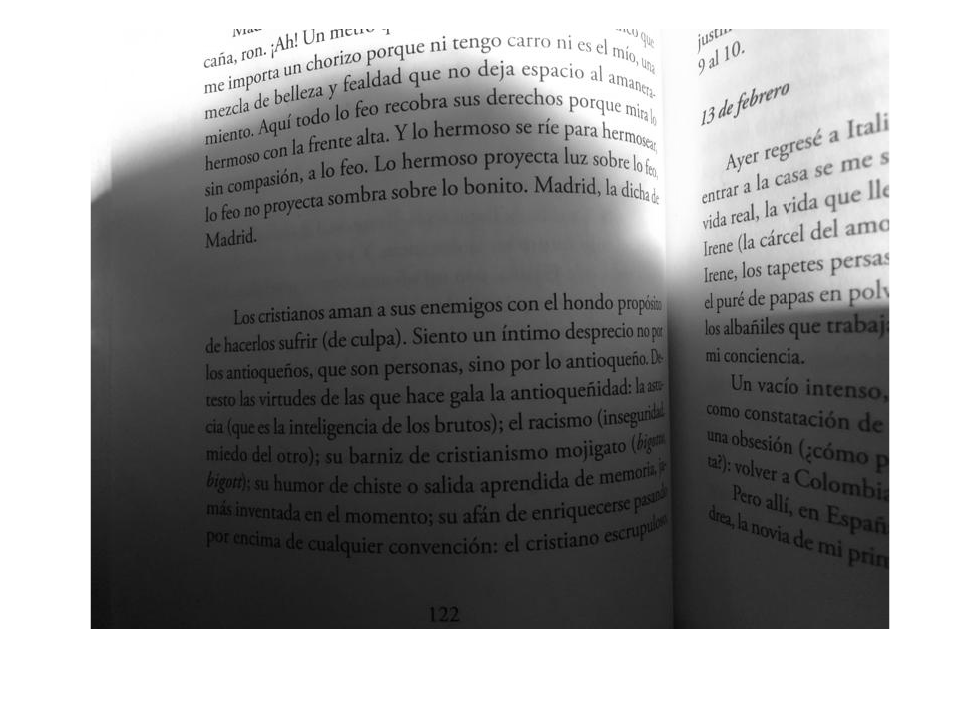

book = imread("./images/book.jpg");
book = im2gray(book);
imshow(book);

## Task 1

In this practice you will adjust the contrast block-by-block using the `blockproc` function.

`imBP` `=` `blockproc``(``im``, blockSize``, @``functionName``)``;`

The block processing function is provided as a local function at the bottom of your script. It scales the intensities of a block to between 0 and 1 using the `rescale` function.

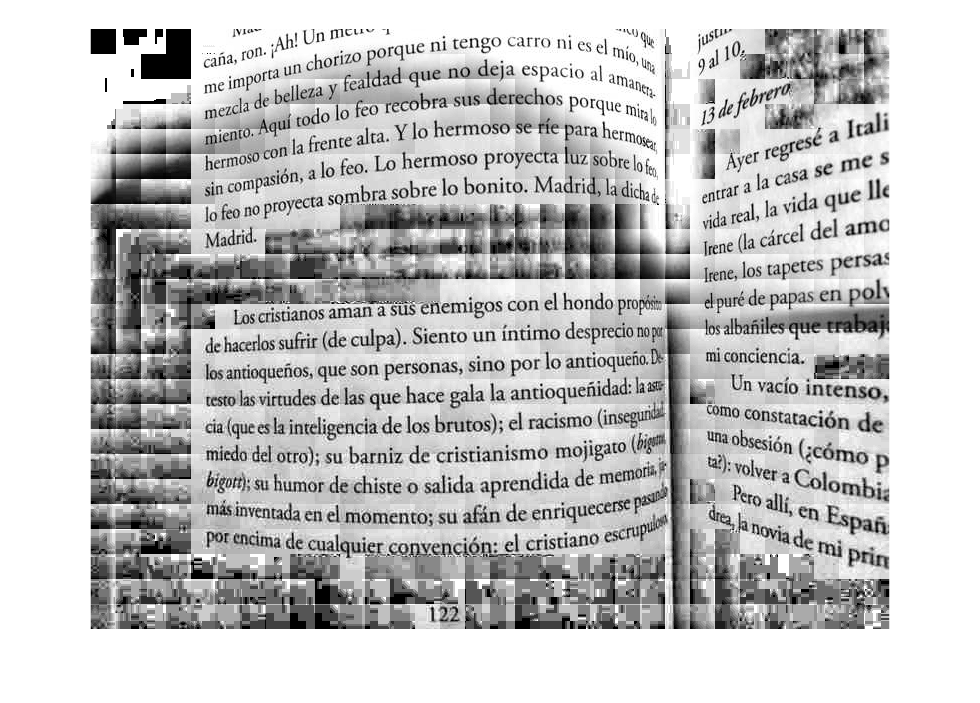

bookRSblck = blockproc(book, [25 25], @adjustContrast);
imshow(bookRSblck)

## Task 2

You can get a closer look at the images by opening the image in a figure window. To do this, mouse over the processed image and click the arrow to the upper right of it.

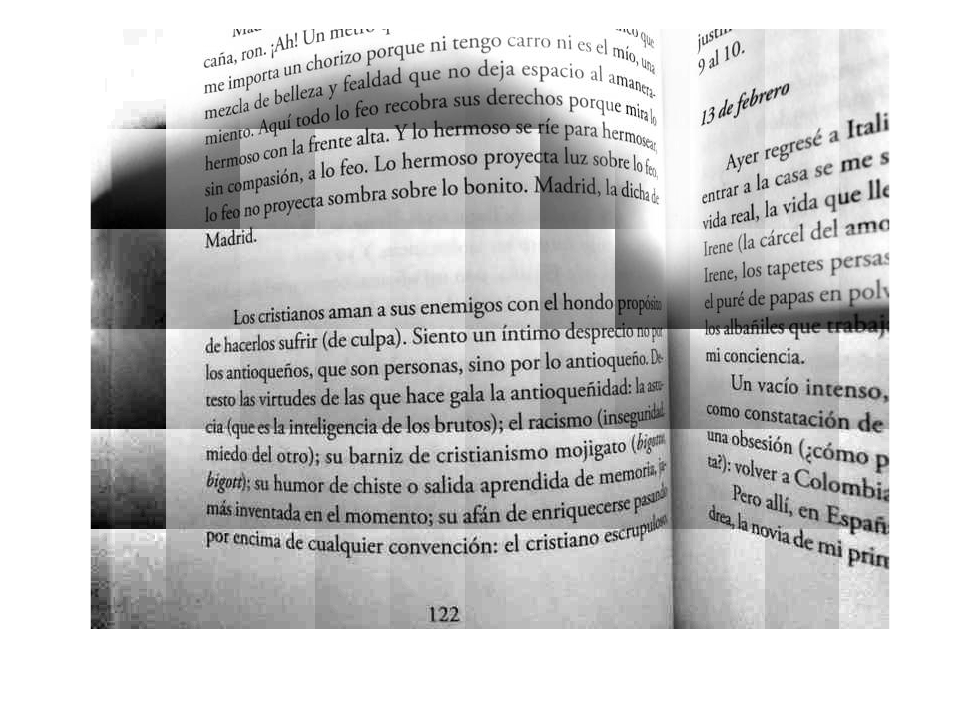

bookRSblckBig = blockproc(book, [100 75], @adjustContrast);
imshow(bookRSblckBig)

function newBlock = adjustContrast(blockStruct)
    % extract the image data for the block being processed 
    % from the structure blockStruct
    block = blockStruct.data;
    
    % rescale this block
    newBlock = rescale(block);
end